% Load projection matrices
projectionMatrices = loadProjectionMatrices();

## Carving Method

% Create voxel space
RESOLUTION = 2;
voxelRanges = [-180 90; ... %X range
                -80 70; ... %Y range
                 20 460];   %Z range
[voxelX, voxelY, voxelZ, voxelValues] = initialiseVoxels(voxelRanges, RESOLUTION);

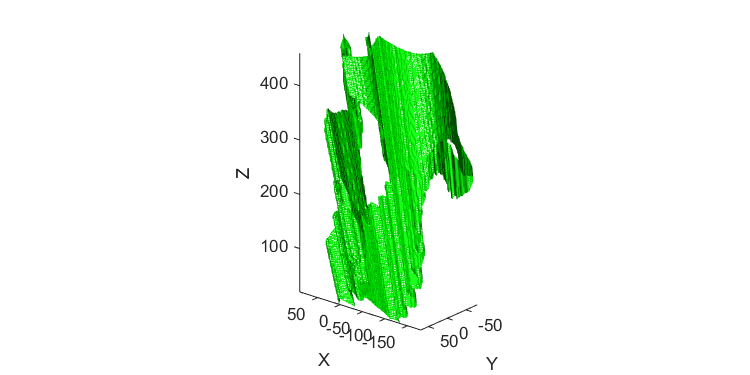

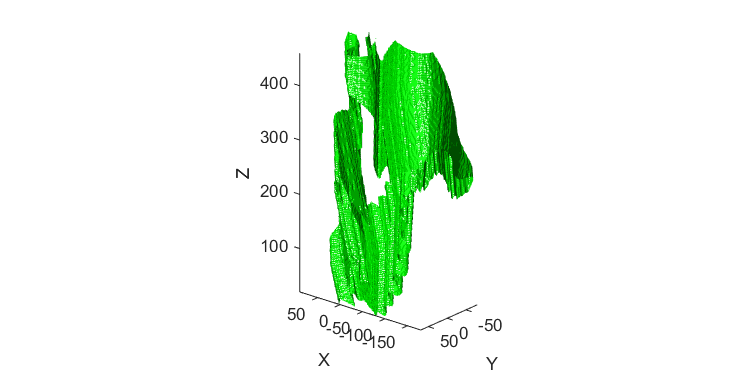

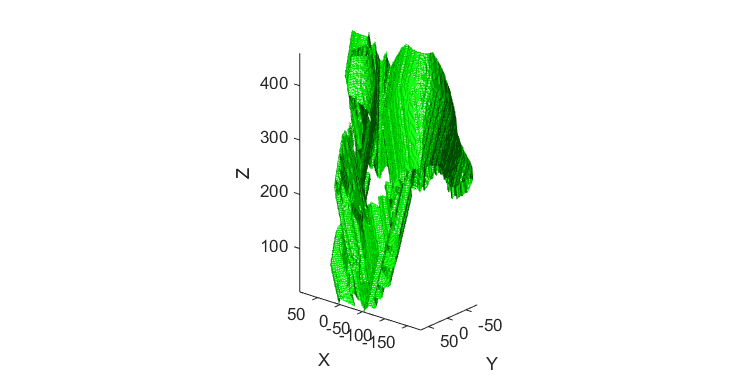

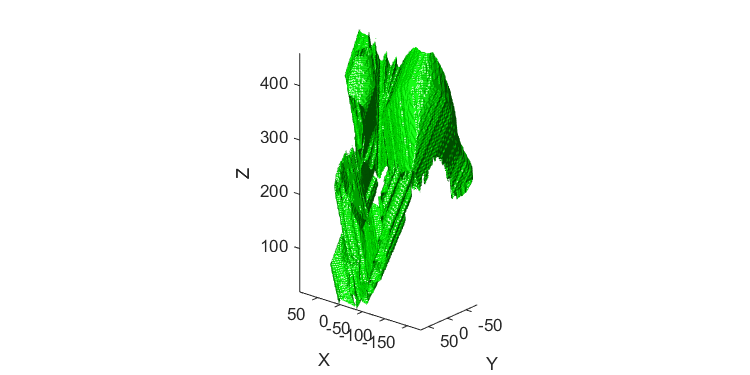

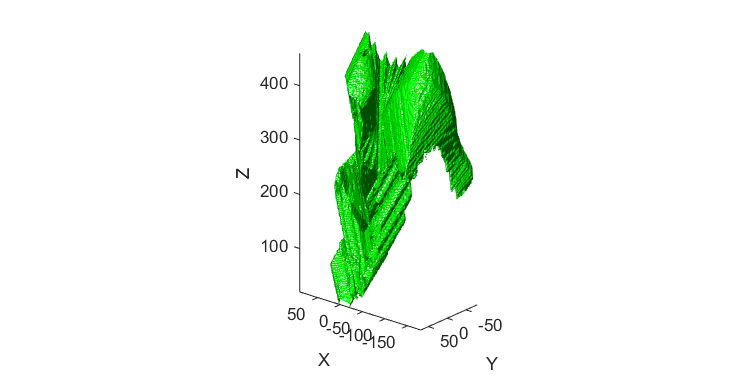

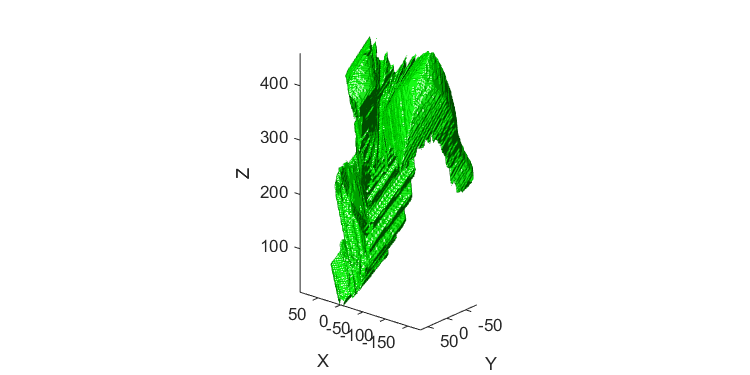

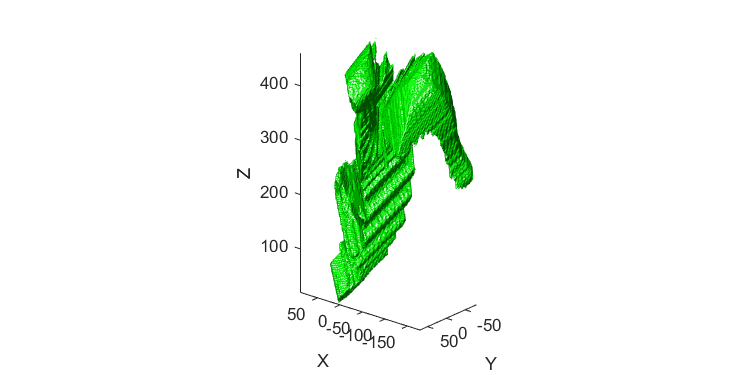

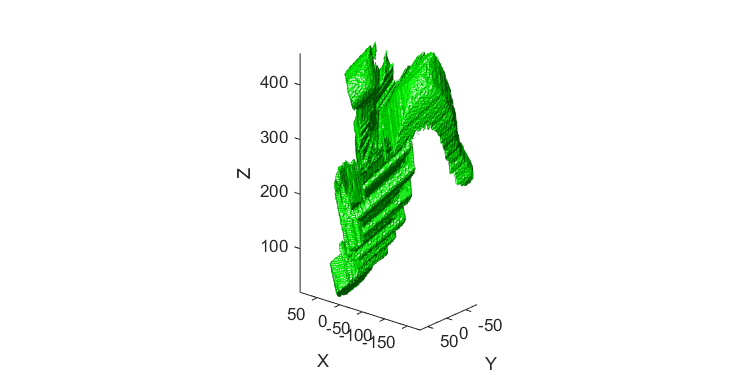

%Carve voxel space from each angle
for i = 1:36
    %Get silhouette
    image = imread(sprintf('dino/dino%02d.jpg', i-1));
    silhouette = createDinoSilhouette(image);
    
    %Project voxels onto silhouette
    [imageX, imageY] = projectOntoImage(projectionMatrices(:,:,i), voxelX, voxelY, voxelZ);
    
    %Crop any projection outside image     
    [imageHeight, imageWidth,~] = size(image);
    cropMask = find((imageX >= 1) & (imageX <= imageWidth) & ...
                    (imageY >= 1) & (imageY <= imageHeight));
    imageX = imageX(cropMask);
    imageY = imageY(cropMask);
    
    % Create silhouette mask
    imageIndices = sub2ind([imageHeight,imageWidth], round(imageY), round(imageX));
    silhouetteMask = cropMask(silhouette(imageIndices) >= 1);

    % Carve silhouette into voxels
    voxelX = voxelX(silhouetteMask);
    voxelY = voxelY(silhouetteMask);
    voxelZ = voxelZ(silhouetteMask);
    voxelValues = voxelValues(silhouetteMask);
    
    % Show Result
    figure('Position', [100 100 600 300]);
    plotDino(voxelX, voxelY, voxelZ, voxelValues);
end

## Voting Method

% Create voxel space
RESOLUTION = 2;
voxelRanges = [-180 90; ... %X range
                -80 70; ... %Y range
                 20 460];   %Z range
[voxelX, voxelY, voxelZ, voxelValues] = initialiseVoxels(voxelRanges, RESOLUTION);
voxelColours = uint8(zeros(length(voxelValues), 3));

%Carve voxel space from each angle
for i = 1:36
    %Get silhouette
    image = imread(sprintf('dino/dino%02d.jpg', i-1));
    silhouette = createDinoSilhouette(image);
    
    %Project voxels onto image
    [projectedX, projectedY] = projectOntoImage(projectionMatrices(:,:,i), voxelX, voxelY, voxelZ);
    
    %Vote 
    [imageHeight, imageWidth,~] = size(image);
    for i = 1:length(projectedX)
        if(projectedY(i) <= imageHeight && projectedY(i) > 0 &&...
           projectedX(i) <= imageWidth && projectedX(i) > 0 &&...
           silhouette(projectedY(i), projectedX(i)) >= 1)
              voxelValues(i) = voxelValues(i) + 1;
        end
   end
end

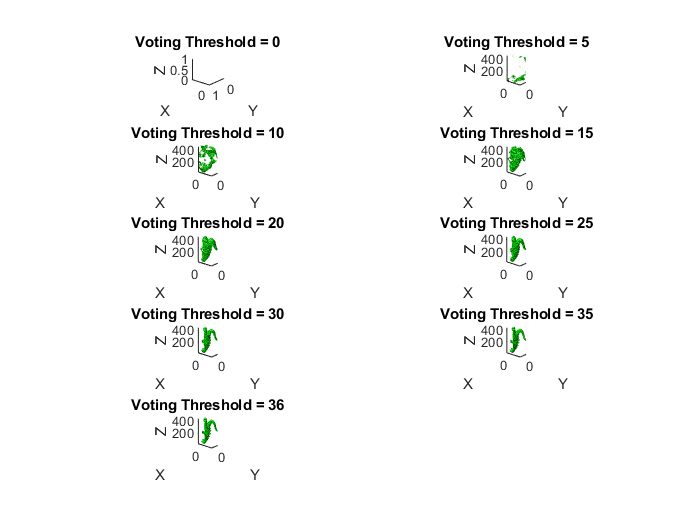

Index exceeds array bounds.

figure();
votingThresholds = [0 5 10 15 20 25 30 35 36]; %40
for i = 1:9    
    % 'Carve' using voting threshold    
    thresholdedVoxelX = voxelX(voxelValues >= votingThresholds(i));
    thresholdedVoxelY = voxelY(voxelValues >= votingThresholds(i));
    thresholdedVoxelZ = voxelZ(voxelValues >= votingThresholds(i));
    thresholdedVoxelValues = voxelValues(voxelValues >= votingThresholds(i));

    % Show Result
    subplot(5,2,i);
    plotDino(thresholdedVoxelX, thresholdedVoxelY, thresholdedVoxelZ, thresholdedVoxelValues);
    title(sprintf('Voting Threshold = %d', votingThresholds(i)));
end

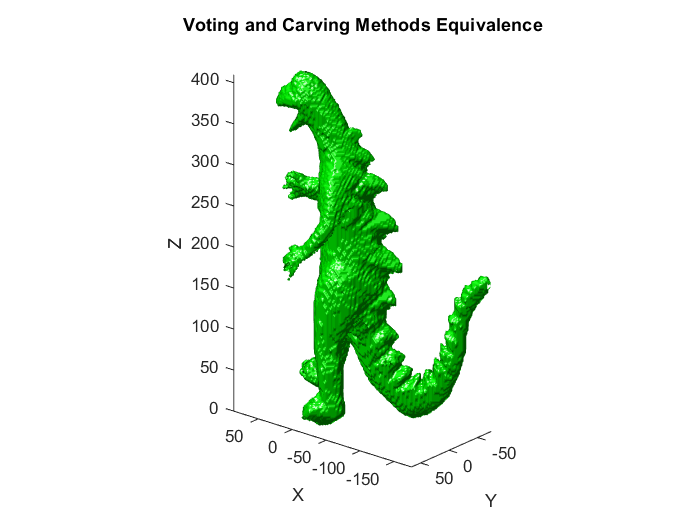

%Plot carving method equivalent
thresholdedVoxelX = voxelX .* (voxelValues >= 36);
thresholdedVoxelY = voxelY .* (voxelValues >= 36);
thresholdedVoxelZ = voxelZ .* (voxelValues >= 36);
thresholdedVoxelColours = voxelColours .* uint8(repmat(voxelValues >= 36, 1, 3));
thresholdedVoxelValues = voxelValues .* (voxelValues >= 36);

%Correct upside-downness 
thresholdedVoxelZ = max(thresholdedVoxelZ(:)) - thresholdedVoxelZ;

% Show Result
figure();
p = plotDino(thresholdedVoxelX, thresholdedVoxelY, thresholdedVoxelZ, thresholdedVoxelValues);
% plotColourDino(thresholdedVoxelX, thresholdedVoxelY, thresholdedVoxelZ, thresholdedVoxelValues, thresholdedVoxelColours, RESOLUTION);
title('Voting and Carving Methods Equivalence');

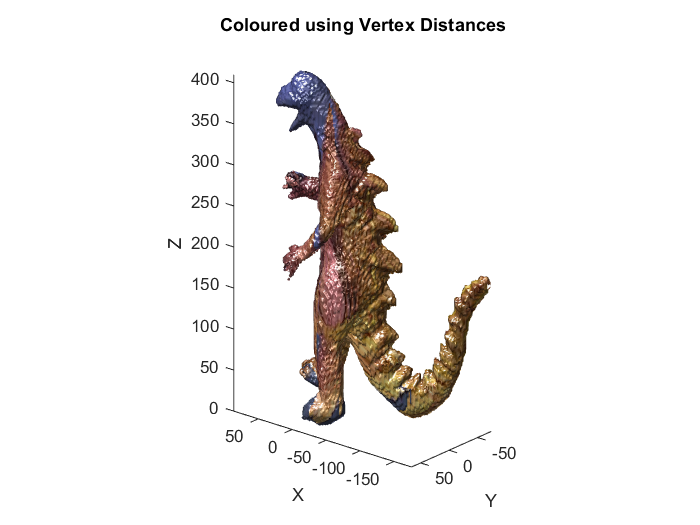

% Colour in dino - well, try to
images = [];
silhouettes = [];
cameraLocations = zeros(size(projectionMatrices,3), 3); 
cameraDirections = zeros(size(projectionMatrices,3), 3);
for i = 1:36
    images = cat(4, images, imread(sprintf('dino/dino%02d.jpg', i-1)));
    silhouettes = cat(3, silhouettes, createDinoSilhouette(images(:,:,:,i)));
    [cameraLocations(i,:), cameraDirections(i,:)] = getCameraLocation(projectionMatrices(:,:,i));
end

% Show Result
figure();
p = plotDino(thresholdedVoxelX, thresholdedVoxelY, thresholdedVoxelZ, thresholdedVoxelValues);
colourDinoUsingDistance(p, images, silhouettes, projectionMatrices, cameraLocations);
title('Coloured using Vertex Distances');


figure();
p = plotDino(thresholdedVoxelX, thresholdedVoxelY, thresholdedVoxelZ, thresholdedVoxelValues);
colourDinoUsingNormals(p, images, silhouettes, projectionMatrices, cameraDirections);
title('Coloured using Vertex Normals');

## General Functions

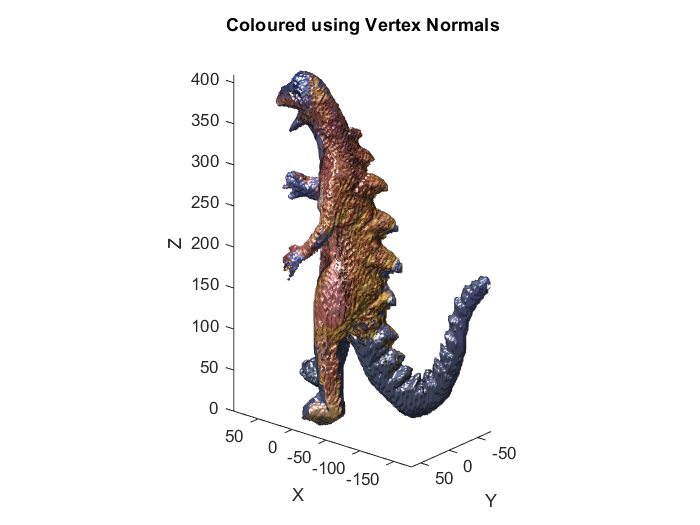

function [voxelX, voxelY, voxelZ, voxelValues] = initialiseVoxels(voxelRanges, resolution)

    x = voxelRanges(1,1):resolution:voxelRanges(1,2);
    y = voxelRanges(2,1):resolution:voxelRanges(2,2);
    z = voxelRanges(3,1):resolution:voxelRanges(3,2);
    
    [X, Y, Z] = meshgrid(x, y, z);
    voxelX = X(:);
    voxelY = Y(:);
    voxelZ = Z(:);
    voxelValues = ones(numel(X), 1);
end

function [imageX, imageY] = projectOntoImage(projectionMatrix, voxelX, voxelY, voxelZ)
    z = projectionMatrix(3,1) * voxelX ...
      + projectionMatrix(3,2) * voxelY...
      + projectionMatrix(3,3) * voxelZ ...
      + projectionMatrix(3,4);
    
    imageX = round((projectionMatrix(1,1) * voxelX ...
                  + projectionMatrix(1,2) * voxelY...
                  + projectionMatrix(1,3) * voxelZ ...
                  + projectionMatrix(1,4)) ./ z);  
        
    imageY = round((projectionMatrix(2,1) * voxelX ...
                  + projectionMatrix(2,2) * voxelY...
                  + projectionMatrix(2,3) * voxelZ ...
                  + projectionMatrix(2,4)) ./ z);  
end

function [ptch] = plotDino(voxelX, voxelY, voxelZ, voxelValues)
    % First grid the data
    ux = unique(voxelX);
    uy = unique(voxelY);
    uz = unique(voxelZ);

    % Convert to a grid
    [X,Y,Z] = meshgrid(ux, uy, uz);
    
    % Create an empty voxel grid, then fill only those elements in voxels
    V = zeros(size(X));
    N = numel(voxelX);
    for ii=1:N
        ix = (ux == voxelX(ii));
        iy = (uy == voxelY(ii));
        iz = (uz == voxelZ(ii));
        V(iy,ix,iz) = voxelValues(ii);
    end
    
    % Now draw it
    ptch = patch(isosurface(X, Y, Z, V, 0.5));
    isonormals(X, Y, Z, V, ptch)
    set(ptch, 'FaceColor', 'g', 'EdgeColor', 'none' );

    set(gca,'DataAspectRatio',[1 1 1]);
    xlabel('X');
    ylabel('Y');
    zlabel('Z');
    view(-140,22)
    lighting('gouraud')
    camlight('left')
    axis('tight')
end

function colourDinoUsingDistance(p, images, silhouettes, projectionMatrices, cameraLocations)
    vertices = get(p, 'Vertices');
    nc = uint8(zeros(size(vertices, 1), 3));
        
    for i = 1:size(vertices, 1)
        [~, closestCameraIndex] = pdist2(cameraLocations, vertices(i, :), 'squaredeuclidean', 'Smallest', 1);
        [imageX, imageY] = projectOntoImage(projectionMatrices(:,:,closestCameraIndex), vertices(i,1), vertices(i,2), vertices(i,3));
        image = images(:,:,:,closestCameraIndex);
        nc(i,:) = reshape((image(imageY, imageX, :)), 1, 3);
    end
    
    set(p, 'FaceVertexCData', nc, 'FaceColor', 'interp');
    p.EdgeColor = 'none';
end

function colourDinoUsingNormals(p, images, silhouettes, projectionMatrices, cameraDirections)

    vertices = get(p, 'Vertices');
    vertexNormals = get(p, 'VertexNormals');
    nc = uint8(zeros(size(vertexNormals, 1), 3));
        
    for i = 1:size(vertexNormals, 1)
        angles = vertexNormals(i,:)*cameraDirections'./norm(vertexNormals(i,:));
        [~, cameraOrder] = sort(angles, 'ascend');
        cameraIndex = 1;
        [imageX, imageY] = projectOntoImage(projectionMatrices(:,:,cameraOrder(cameraIndex)), vertices(i,1), vertices(i,2), vertices(i,3));
        while((imageX < 1) || (imageX > size(images,2)) || (imageY < 1) || (imageY > size(images, 1)))
            cameraIndex = cameraIndex + 1;
            [imageX, imageY] = projectOntoImage(projectionMatrices(:,:,cameraOrder(cameraIndex)), vertices(i,1), vertices(i,2), vertices(i,3));
        end
        yeet = images(:,:,:,cameraOrder(cameraIndex));
        nc(i,:) = reshape((yeet(imageY, imageX, :)), 1, 3);
    end

    set(p, 'FaceVertexCData', nc, 'FaceColor', 'interp');
    p.EdgeColor = 'none';
end

function [location, direction] = getCameraLocation(projectionMatrix)
    [q,r] = qr(inv(projectionMatrix(1:3,1:3)));
    invK = r(1:3,1:3);
    R = inv(q);
    
    if det( R ) < 0
        R = -R;
        invK = -invK;
    end
    t = invK*projectionMatrix(:,4);
    
    location = -q * t; 
    
    imageCenter = [360; 288; 1];
    X = R' * (invK * imageCenter);
    direction = X ./ norm(X);
    
end